clear; clear path; clc;
% cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG


approximate zoh plant

riseTime = 0.052333; %seconds
Ts = riseTime/10;
Psz = Ps*exp(-Ts/2);

we now tune a contiunous pid on the continuous estimator of zoh plant

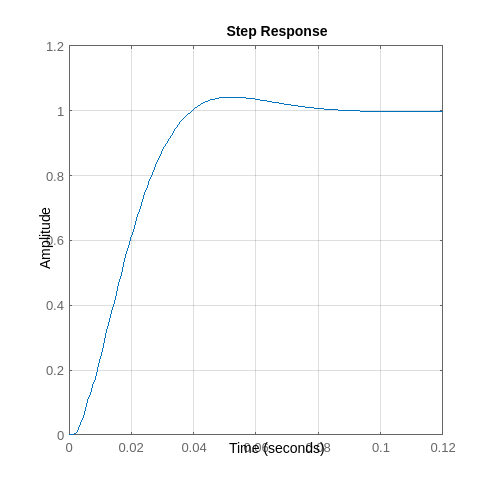

P = 0;
I = 0;
D = 60;
N = 120;
Csz = pidGen(P,I,D,N,1);
Csz1 = Csz;

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Csz*Psz/(1+Csz*Psz)); grid on;

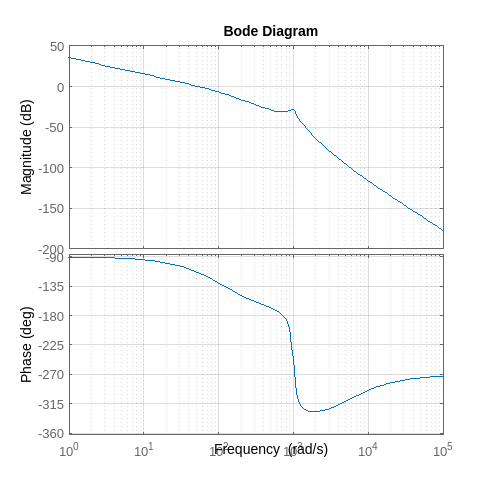


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz); grid on;


stepinfo(step(Csz*Psz/(1+Csz*Psz)))

ans = struct with fields:
         RiseTime: 33.11
    TransientTime: 94.402
     SettlingTime: 94.402
      SettlingMin: 0.90013
      SettlingMax: 1.0422
        Overshoot: 4.402
       Undershoot: 0
             Peak: 1.0422
         PeakTime: 70


we will now fix the input gain saturation

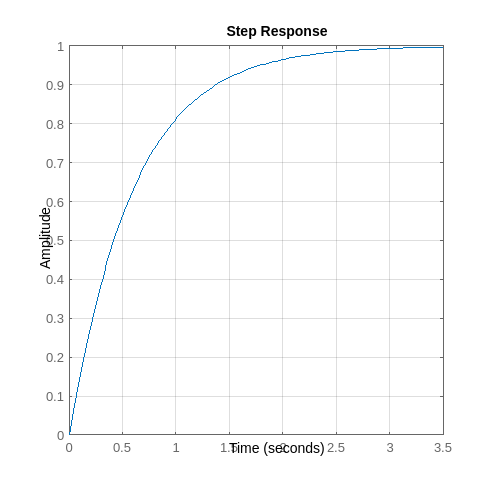

uMax = max(step(Csz/(1+Csz*Psz)));
Csz = pidGen(P,I,D,N,200/uMax);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Csz*Psz/(1+Csz*Psz)); grid on;

info = stepinfo(Csz*Psz/(1+Csz*Psz));
info.Overshoot

ans =      0


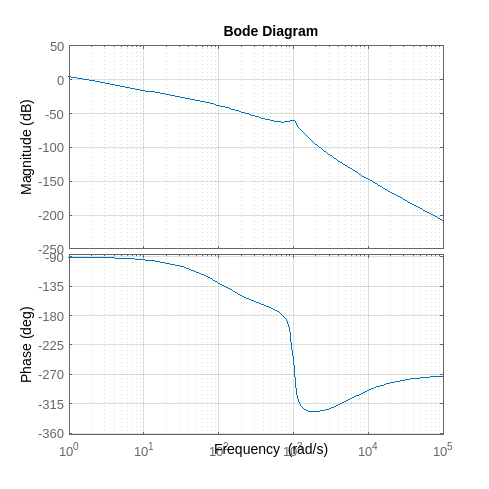


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz); grid on;

We will now get the actual discrete system

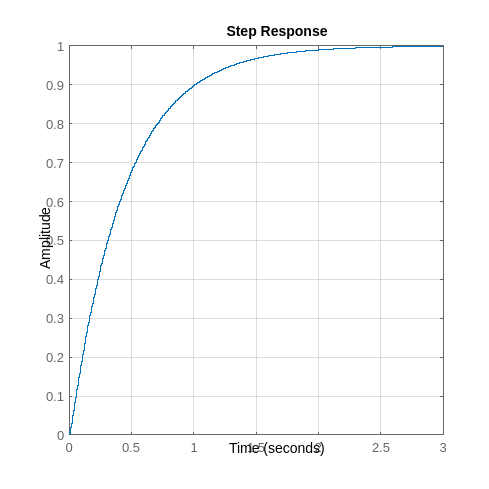

Pz = c2d(Ps,Ts);
Cz = c2d(Csz,Ts);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Cz*Pz/(1+Cz*Pz)); grid on;

info = stepinfo(Csz*Psz/(1+Csz*Psz));
info.Overshoot

ans =      0


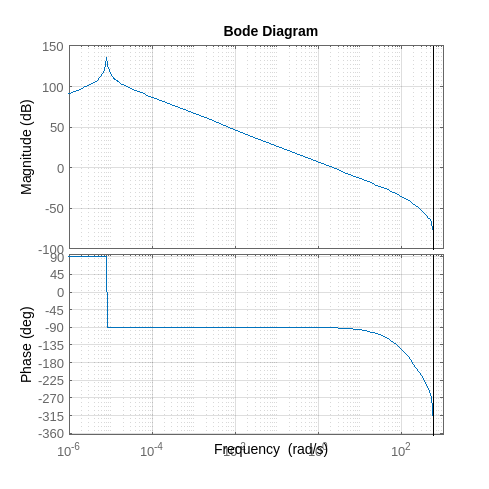


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Cz*Pz); grid on;

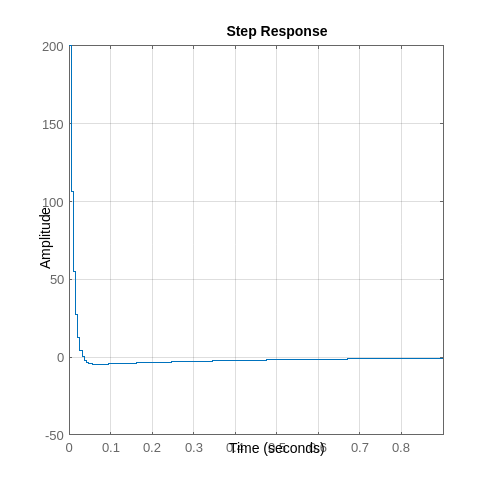


figure('Position',[0 0 1000 1000]); clf; hold on;
step(Cz/(1+Cz*Pz)); grid on;

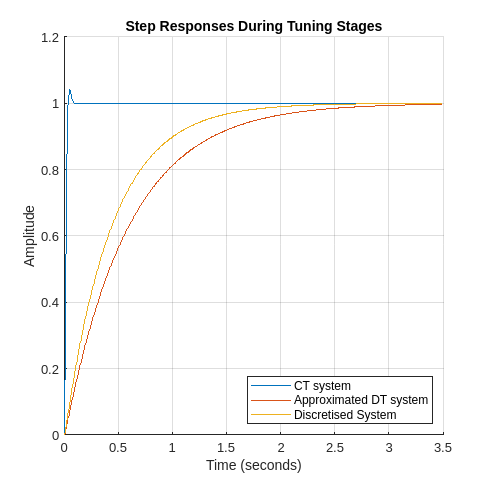

t = 0:Ts:3.5;
y1 = step(Csz1*Psz/(1+Csz1*Psz),t);
y2 = step(Csz*Psz/(1+Csz*Psz),t);
y3 = step(Cz*Pz/(1+Cz*Pz),t);

figure('Position',[0 0 1000 1000]); clf; hold on;
plot(t,y1)
plot(t,y2)
plot(t,y3); grid on;
legend("CT system","Approximated DT system","Discretised System","Location","southeast")
title("Step Responses During Tuning Stages")
xlabel("Time (seconds)")
ylabel("Amplitude")


t = 0:Ts:0.12;
u1 = step(Csz1/(1+Csz1*Psz),t);
u2 = step(Csz/(1+Csz*Psz),t);
u3 = step(Cz/(1+Cz*Pz),t);

figure('Position',[0 0 1000 1000]); clf; hold on;
% plot(t,u1)
plot(t,u2)
plot(t,u3); grid on;
legend("CT system","Approximated DT system","Discretised System","Location","southeast")

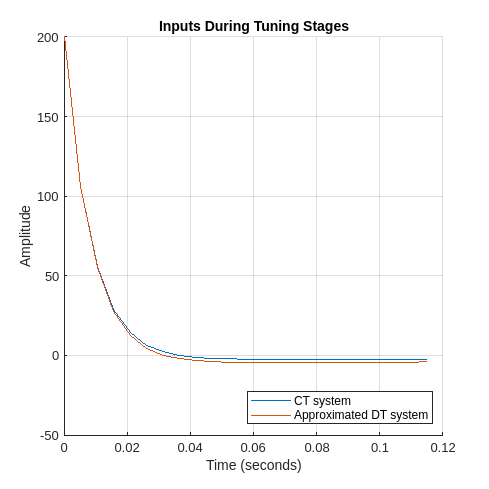


title("Inputs During Tuning Stages")
xlabel("Time (seconds)")
ylabel("Amplitude")